# Chapter 04a - Machine Learning with MATLAB.

Author: Yijie ZHENG (Amy)

Reference files for this chapter:

- ../Test_Data/rawSensorData_train.mat

- ../Test_Data/rawSensorData_test.mat

- Wstd.m

- Wmean.m

- plotRawSensorData.m

## Machine Learning with Matlab

*Machine learning* teaches computers to do what comes naturally to humans: learn from experience. Machine learning algorithms use computational methods to “learn” information directly from data without relying on a predetermined equation as a model. The algorithms adaptively improve their performance as the number of samples available for learning increases.

[https://uk.mathworks.com/help/stats/machine-learning-in-matlab.html](https://uk.mathworks.com/help/stats/machine-learning-in-matlab.html) 

### Train Classification Models in Classification Learner App

#### Description of the Data (rawSensorData_train/test.mat)

`The dataset consists of accelerometer and gyroscope data captured at 50Hz. The activities performed by the subject include: 'Walking', 'ClimbingStairs', 'Sitting', 'Standing',and 'Laying'`

- *total_acc_(x/y/z)_train : *Raw accelerometer sensor data

- *body_gyro_(x/y/z)_train : *Raw gyroscope sensor data

- *trainActivity :* Training data labels

- *testActivity :* Test data labels

#### **Load Training Data**

load rawSensorData_train.mat

#### **Display data summary**

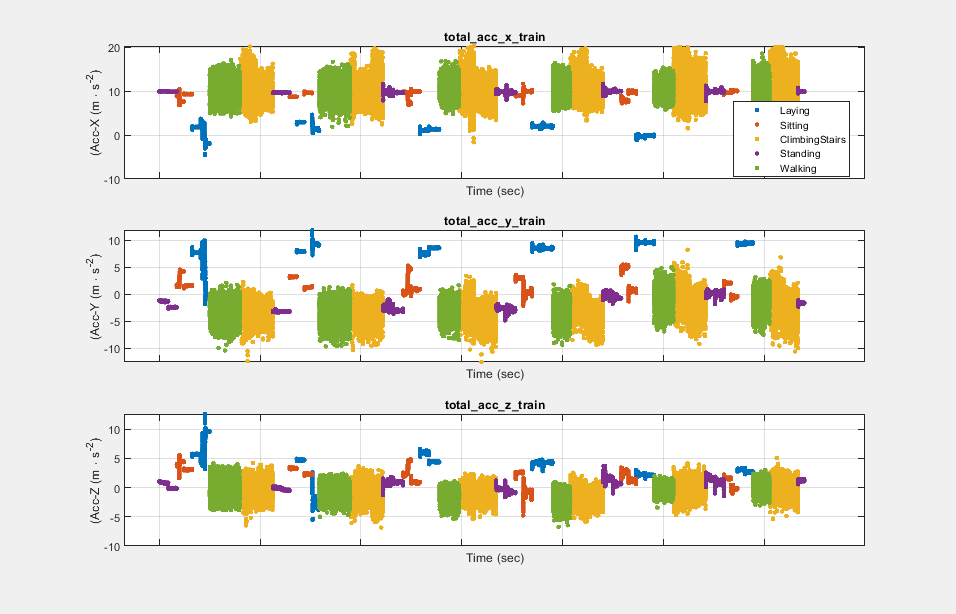

plotRawSensorData(total_acc_x_train, total_acc_y_train, ...
    total_acc_z_train,trainActivity,1000)

#### **Create Table variable**

rawSensorDataTrain = table(...
    total_acc_x_train, total_acc_y_train, total_acc_z_train, ...
    body_gyro_x_train, body_gyro_y_train, body_gyro_z_train);

#### Train a model and assess its performance using Classification Learner

Train on raw data

classificationLearner

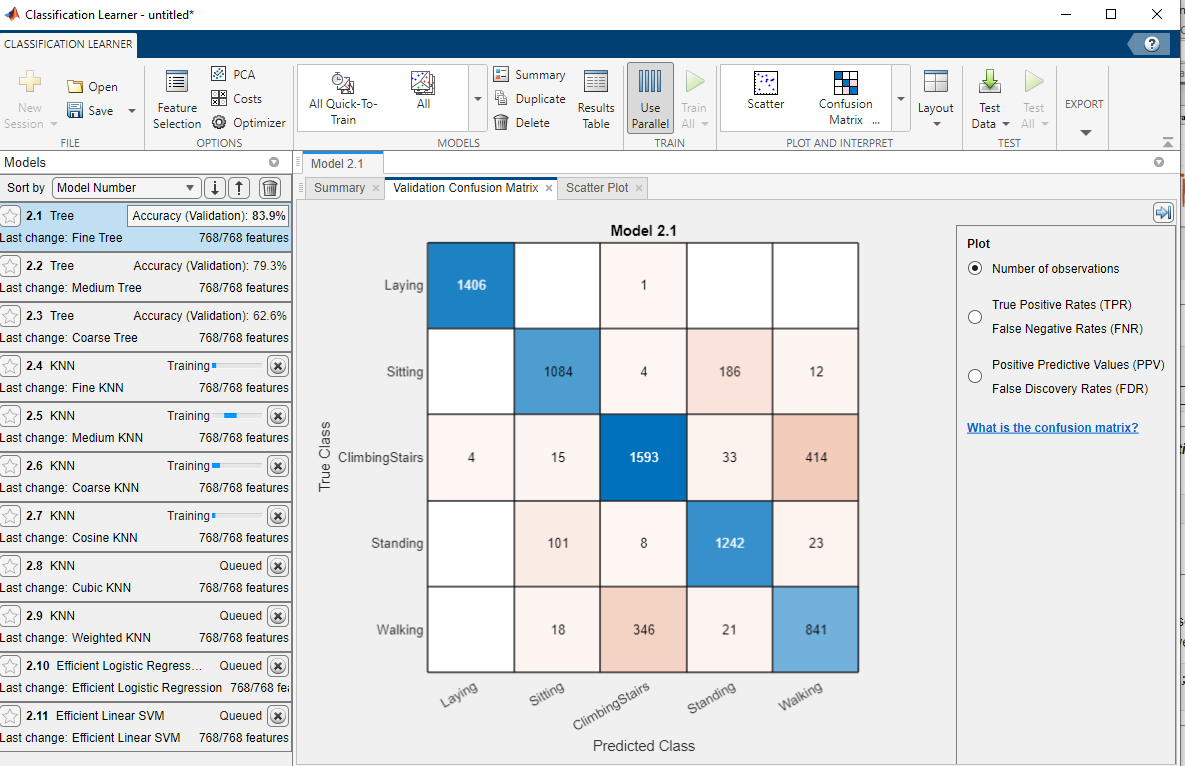

Enable PCA

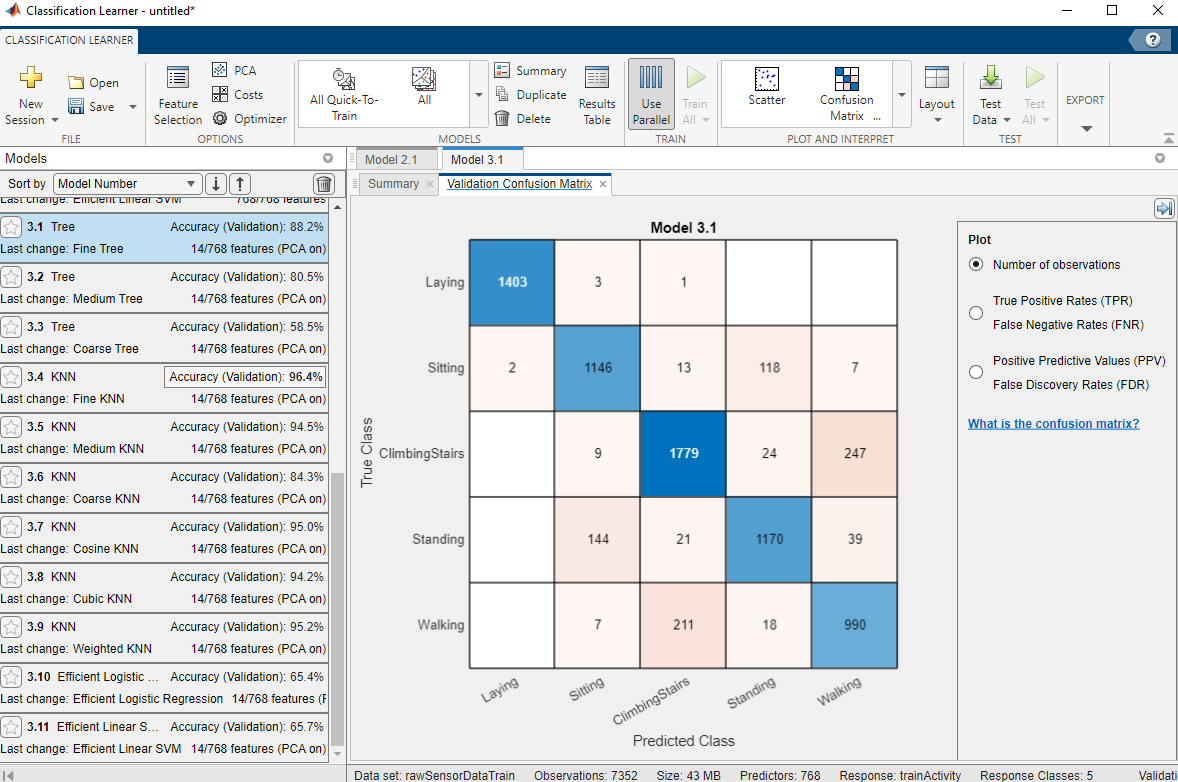

#### Pre-process Training Data: Feature Extraction

Lets start with a simple preprocessing technique. Since the raw sensor data contain fixed-width sliding windows of 2.56sec (128 readings/window) lets start with a simple average feature for every 128 points

%% calculate the mean value
T_mean = varfun(@Wmean,rawSensorDataTrain);

%% calculate the std value
T_stdv = varfun(@Wstd,rawSensorDataTrain);


%% update the table
humanActivityData = [T_mean, T_stdv];
humanActivityData.activity = trainActivity;
humanActivityData.Properties.VariableNames = {'input1', 'input2', 'input3',...
    'input4','input5','input6','input7','input8','input9','input10',...
    'input11','input12','output'};


#### *Train a model and assess its performance using Classification Learner*

Train on pre-processed data

classificationLearner

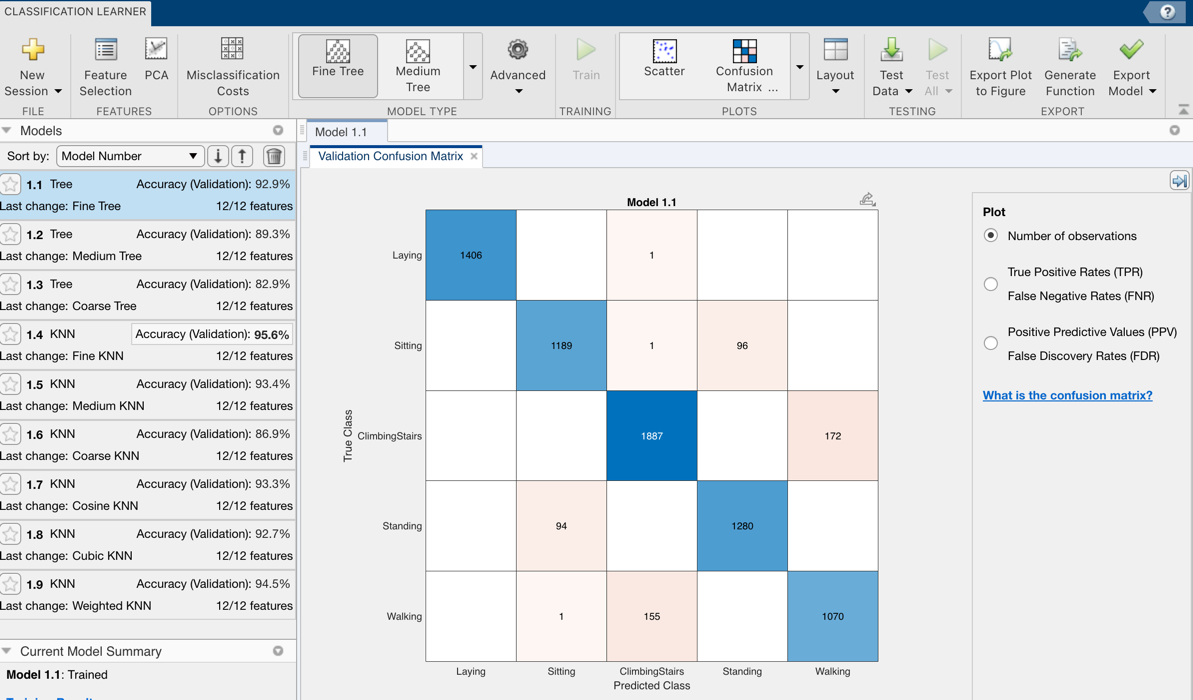

#### Export trained model

*Name: 'trainedModel'*

#### **Make Predictions for New Data Using Exported Model**

%% load test data
load rawSensorData_test
% Step 1: Create the table
rawSensorDataTest = table(...
    total_acc_x_test, total_acc_y_test, total_acc_z_test, ...
    body_gyro_x_test, body_gyro_y_test, body_gyro_z_test);

% Step 2: Extract features from raw sensor data
T_mean = varfun(@Wmean, rawSensorDataTest);
T_stdv = varfun(@Wstd,rawSensorDataTest);

humanActivityData2 = [T_mean, T_stdv];
humanActivityData2.activity = testActivity;
humanActivityData2.Properties.VariableNames = {'input1', 'input2', 'input3',...
    'input4','input5','input6','input7','input8','input9','input10',...
    'input11','input12','output'};


*Use Classification Learner App*

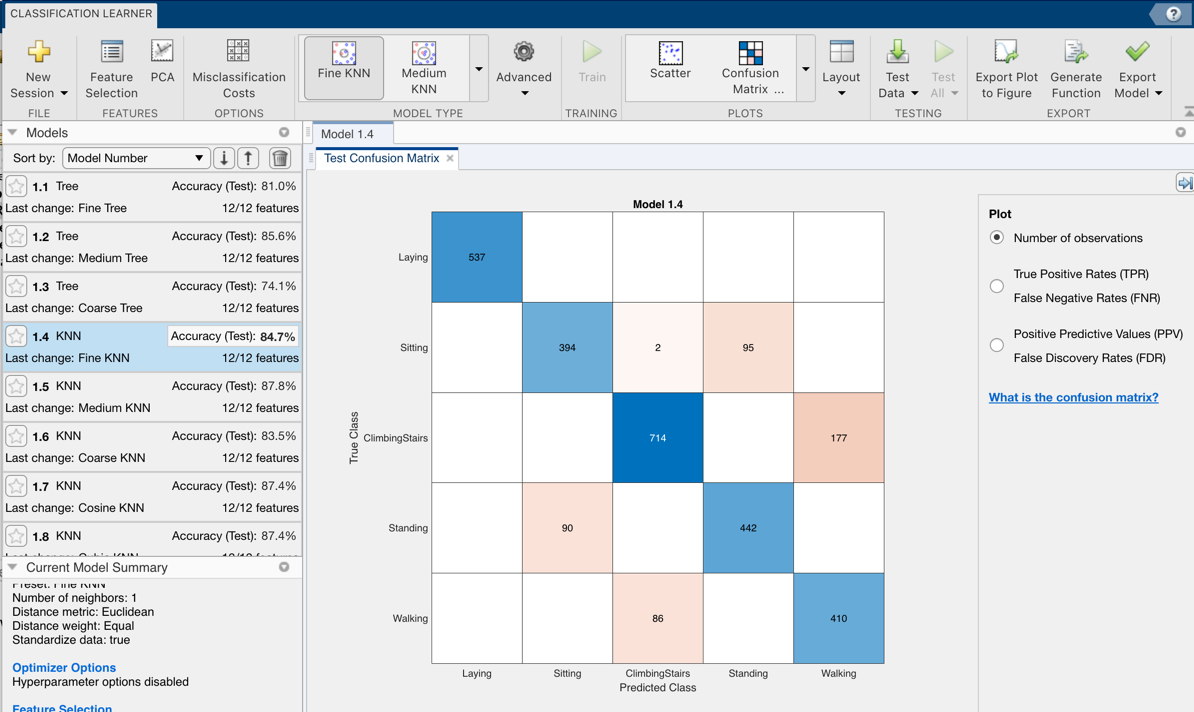

*Use function 'predictFcn'*

[yfit,scores] = trainedModel.predictFcn(humanActivityData2)
trueLabels = humanActivityData2.output; 
figure;
confusionchart(trueLabels, yfit);
title('Confusion Matrix');